# Surface reflectance properties

#sec-lightfield-properties

Show the basis functions for surface reflectances.  Then calculate the product of some daylights and surfaces to illustrate the variation in the incident light field with changes in ambient illumination.

Use the Mike Vrhel data set as the example, though perhaps the USGS data set too for materials?

Any chance we can find some standard functions for BRDFs and specular reflection that include both angle and wavelength?

imgdir = '~/Documents/FISE-git/chapters/images/lightfields';
wave = 400:1:700;

## Typical reflectance functions

These are samples of clothing, but many other types of objects have smooth spectral reflectance functions, too.

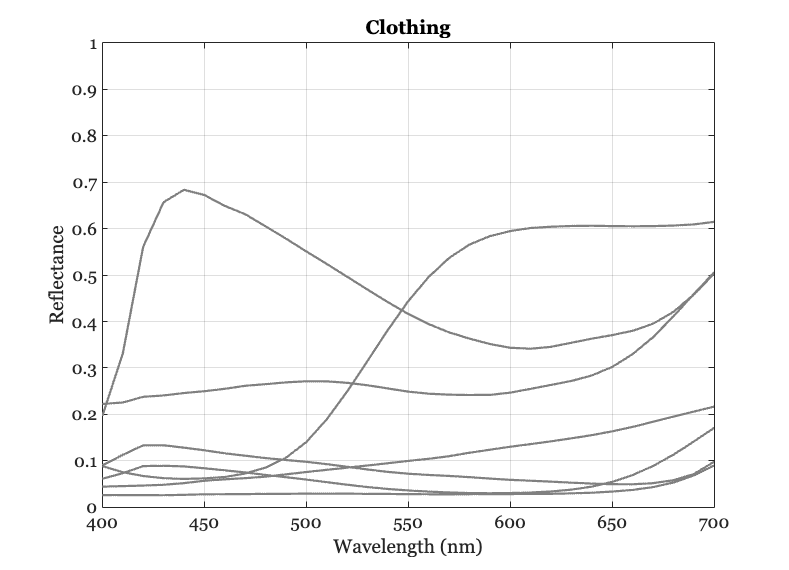

[clothes,~,comment] = ieReadSpectra('Clothes_Vhrel',wave);
plotReflectance(wave,clothes(:,1:6:end),...
    'Color',[0.5 0.5 0.5], ...
    'title','Clothing');
set(gca,'ylim',[0 1]);

%{
exportgraphics(gca,fullfile(imgdir,'01-reflectance-clothes.png'),...
    'Resolution',150);
%}

## Sample linear models

We can compare the linear models from different groups of surfaces.

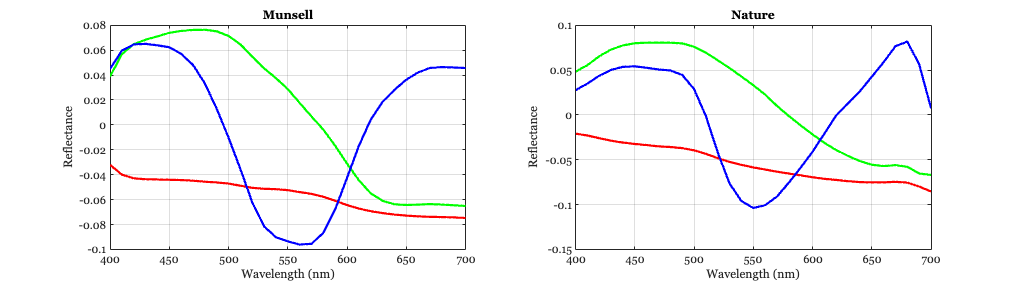

% Should we have a normalized wave option for this method?
munsell = ieReadSpectra('MunsellSamples_Vhrel',wave);
nature  = ieReadSpectra('Nature_Vhrel',wave);

[Um, Sm, ~] = svd(munsell,'econ');
[Un, Sn, ~] = svd(nature,'econ');

hdl = ieFigure([],'wide'); tiledlayout(1,2);
nexttile;
plotReflectance(wave,Um(:,1:3),'hdl',hdl, 'title','Munsell'); hold on;
nexttile
plotReflectance(wave,Un(:,1:3),'hdl',hdl,'title','Nature');
%{
exportgraphics(gca,fullfile(imgdir,'01-reflectance-bases.png'),...
    'Resolution',150);

%}

### See whether the bases are close to a linear transformation

Um=Un*T

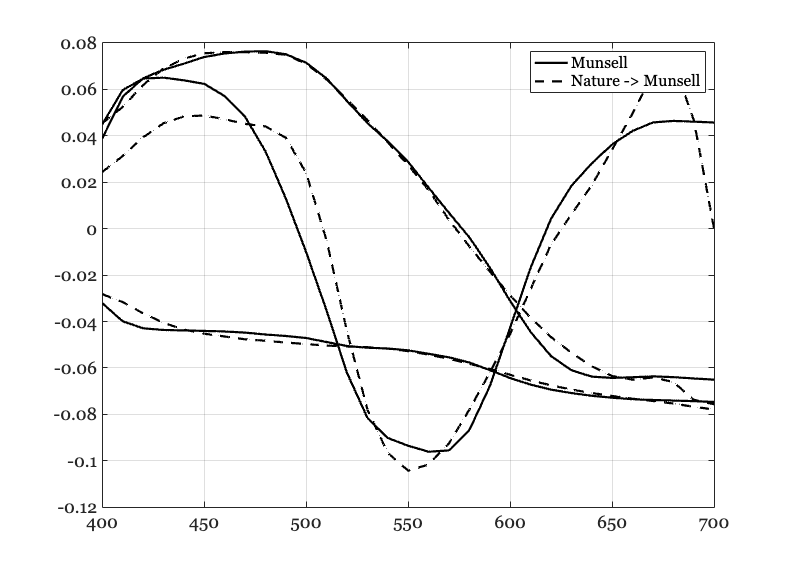

T = pinv(Un(:,1:3))*Um(:,1:3);
UmEst = Un(:,1:3)*T;

ieFigure;
hA = plot(wave,Um(:,1:3),'k-','LineWidth',2); hold on;
hB = plot(wave,UmEst,'k--','LineWidth',2); hold on;
legend([hA(1) hB(1)],{'Munsell','Nature -> Munsell'});
grid on;
%{
exportgraphics(gca,fullfile(imgdir,'01-reflectance-basis-match.png'),...
    'Resolution',150);

%}




## The Judd Macadam Wyszecki Daylight model

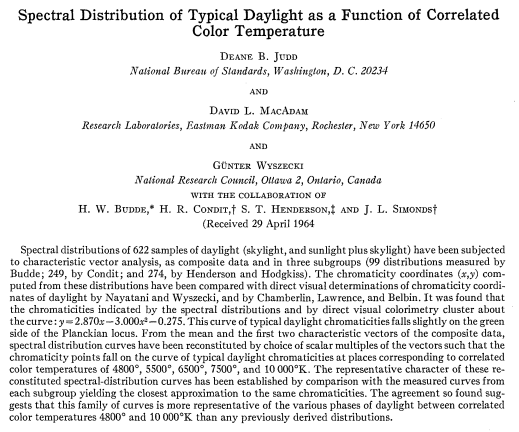%

This group and several others measured the spectral distributions of irradiance at the Earth's surface.  The found a two-dimensional linear model that described a large percentage of the variance of their (normalized) data (mean plus two basis vectors).  These have been confirmed by other authors, and here is the models that has been adopted as a CIE standard.

This plot shows the three functions along with a circle at several of the Fraunhofer lines.  You can see how the small discontinuities in the mean at most of these lines.

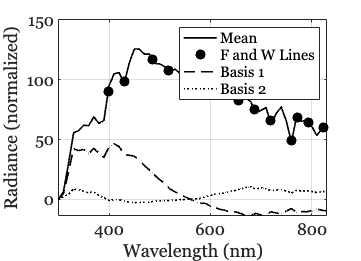

[dayBasis,wave] = ieReadSpectra('cieDaylightBasis');

ieFigure;
sym = {'k-','k--','k:'};
for ii=1:3
    plot(wave,dayBasis(:,ii),sym{ii},'LineWidth',1.5); hold on;
    if ii==1
        tmp = interp1(wave,dayBasis(:,ii),[earthLines, solarLines]);
        plot([earthLines, solarLines],tmp,'ko',...
            'MarkerSize',8,'MarkerFaceColor','k');
    end
end
grid on;
set(gca,'xlim',[300 830]);
legend({'Mean','F and W Lines','Basis 1','Basis 2'});
xlabel('Wavelength (nm)'); ylabel('Radiance (normalized)');


%{
exportgraphics(gca,fullfile(imgdir,'01-solar-basis.png'),...
    'Resolution',150);
%}


## Stanford sunlight

These are the average daylight SPD measurements, across an entire year, made by Jeff DiCarlo outside his office window at Stanford.  The solid curve shows the measurement, the '*' are Fraunhofer lines, and the dashed curve is the fit to the data from the CIE daylight basis functions.

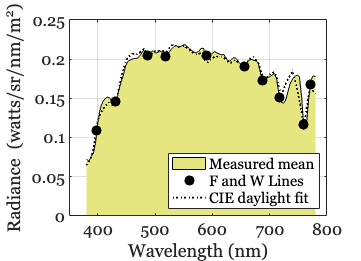

[spd,wave] = ieReadSpectra('daylightStanford');
spdM = mean(spd,2);

ieFigure;
% plot(wave,spdM,'k-','LineWidth',1.5); hold on;
hA = area(wave,spdM,'FaceColor',[0.9 0.9 0.5]); hold on;

% {
tmp = interp1(wave,spdM,[earthLines, solarLines]);
hB = plot([earthLines, solarLines],tmp,'ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','k');
%}

dayBasis = ieReadSpectra('cieDaylightBasis',wave);
wgts = pinv(dayBasis)*spdM;
pred = dayBasis*wgts;
hC = plot(wave,pred,'k:','LineWidth',1.5);

grid on;
set(gca,'xlim',[350 800]);
xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2)');
legend([hA,hB,hC],{'Measured mean','F and W Lines','CIE daylight fit'},'location','southeast');

%{
exportgraphics(gca,fullfile(imgdir,'01-solar-stanford.png'),...
    'Resolution',150);

%}
